#### Plotting the IRS's SNR in dB

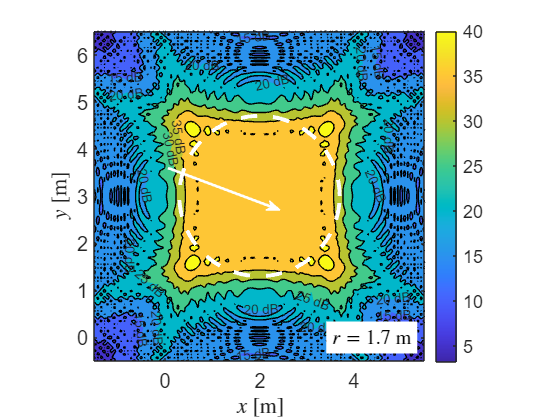

close all;

y_points = p_center(2)+grid_point;
z_points = p_center(3)+grid_point;
[Y,Z]=meshgrid(y_points,z_points);

[M,c]=contourf(Y,Z,pow2db(SNR),"ShowText",true); hold on;
colorbar
c.LabelFormat="%0.0f dB";
c.LabelSpacing=1000;
c.FaceAlpha=1;

%plotting the circle
center=[2 3];
r = 1.7;% radius
q = 0:0.01:2*pi; % angle 0 to 360 degrees in radian
x = r*cos(q)+center(1);    % cartesian x coordinate
y = r*sin(q)+center(2);    % cartesian y coordinate
plot(x,y,'Color','white','LineStyle','--','LineWidth',3);

annotation("arrow",[0.3 0.5],[0.6 0.5],'Color','white','LineWidth',2);
text(3.5,0,strcat('$r=',num2str(r),'$ m'),'Interpreter','latex','FontSize',fontsize,'BackgroundColor','white');

axis square
xlabel('$x$ [m]','Interpreter','latex');
ylabel('$y$ [m]','Interpreter','latex');
set(gca,'FontSize',fontsize);